# **GPS-denied Orbit Control Analysis**

## State equations:


$$\mathbf{x} = 
\pmatrix{
x \cr
y \cr 
\psi \cr 
\alpha_{az} \cr
R}, 
\mathbf{u} = \pmatrix{\phi}$$


## State Dynamics


$$\frac{d}{dt}\mathbf{x} = f(\mathbf{x},\mathbf{u}) =
\pmatrix{
V_a \cos\psi \cr
V_a \sin\psi \cr
\frac{g}{V_a}\tan\phi \cr
\frac{V_a}{R^2} (x\sin\psi - y\cos\psi) - \frac{g}{V_a}\tan\phi \cr
\frac{V_a}{R}(x\cos\psi + y\sin\psi)
}$$


## Measurement model


$$\mathbf{y} = \pmatrix{\alpha_{az} \cr \alpha_{el}} = h(\mathbf{x},\mathbf{u}) = 
\pmatrix{
- \frac{g}{V_a}\tan\phi \cr
\tan^{-1}(\frac{-h}{R}) - \phi
}$$


Assume Va and h are constants.

## Define and Generate Initial conditions


Va = 20.0;
h = 100.0;
phi = deg2rad(10);
  
dt = 0.01;
ode_dt = dt/100;
x0 = -0;
y0 = -70;
psi0 = 0;
az0 = angle_wrap(pi + atan2(y0,x0) - psi0);
R0 = sqrt(x0^2 + y0^2);

X0 = [x0; y0; psi0; az0; R0];


## Generate and plot trajectories

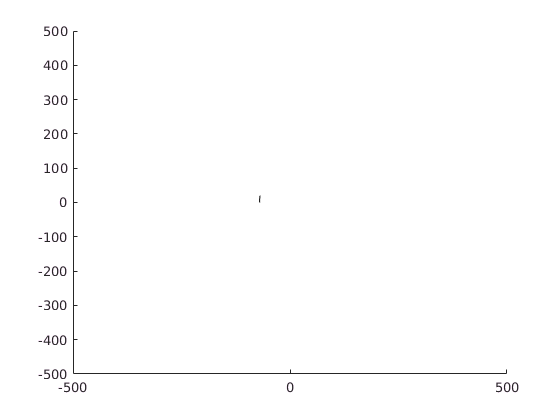

t0 = 0;
tfinal = 1;
N = (tfinal - t0)/dt;
X = X0;

clf;
figure(1)
xlim([-500 500])
ylim([-500 500])
hold on
for i=0:N-1
    t1 = t0 + dt*i;
    t2 = t1 + dt;    
    tspan = [t1:ode_dt:t2];
    [t,X] = ode45(@(t,X) orbit_ode(t,X,phi,Va),tspan,X);
    x = X(:,1);
    y = X(:,2);
    psi = rad2deg(angle_wrap(X(:,3)));
    az = rad2deg(angle_wrap(X(:,4)));
    R = X(:,5);
%     subplot(4,1,1)
    plot(y,x,'k-','linewidth',3)
%     subplot(4,1,2)
%     plot(t,psi)
%     subplot(4,1,3)
%     plot(t,az)
%     subplot(4,1,4)
%     plot(t,R)
    X = X(end,:);
end

## **Define ODE**

function [Xdot] = orbit_ode(t, X, phi, Va)
  g = 9.81;
  
  x = X(1);
  y = X(2);
  psi = X(3);
  az = X(4);
  R = X(5);
  
  xdot = Va*cos(psi);
  ydot = Va*sin(psi);
  psidot = g/Va*tan(phi);
  azdot = Va/R^2 * (x*sin(psi) - y*cos(psi)) - g/Va*tan(phi);
  Rdot = Va/R * (x*cos(psi) + y*sin(psi));
  
  Xdot = [xdot; ydot; psidot; azdot; Rdot];

end

## **Helper functions**

function [out] = angle_wrap(theta)
   angle_mod = mod(theta,2*pi);
   out = zeros(length(angle_mod));
   for i=1:length(angle_mod)
       angle = angle_mod(i);
       if angle > pi
           out(i) = angle - 2*pi;
       elseif angle < -pi
           out(i) = angle_mod + 2*pi;
       else
           out(i) = angle;
       end
   end   
end